% Example_5_1.mlx
%
% This is Example 5.1 from the paper 'Laguerre tessellations and 
% polycrystalline microstructures: A fast algorithm for generating grains 
% of given volumes' by D.P. Bourne, P.J.J. Kok, S.M. Roper, W.D.T. Spanjer
% (Philosophical Magazine 100, 2677-2707, 2020).
%
% Runtime tests for generating 3D periodic Laguerre diagrams representing 
% idealised single phase (SP) and dual phase (DP) steels. 

clear

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Specify whether the Laguerre diagram is periodic (periodic=true) or
% non-periodic (periodic=false)

periodic=true; 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Define the geometry. We create 3D periodic Laguerre diagrams in a 
% rectangular box with vertices (0,0,0), (L1,0,0), (0,L2,0), (0,0,L3), 
% (L1,L2,0), (L1,0,L3), (0,L2,L3), (L1,L2,L3).

L1=100; % length of the box in the x-direction
L2=100; % length of the box in the y-direction
L3=100; % length of the box in the z-direction
bx=[L1,L2,L3];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Specify the number of grains

numGrains=[1000,2000,3000,5000,7500,10000,15000,20000]; 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Set the parameters for Algorithm 2

numLloyd=5; % number of regularisation (Lloyd) iterations
tol=1; % percentage error tolerance for the volumes of the grains

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Choose the optimisation solver

solver='dampedNewton'; % damped Newton method (recommended)
% solver='fminunc'; % slower option

% Remark:
% In the paper 'Laguerre tessellations and polycrystalline microstructures:
% A fast algorithm for generating grains of given volumes' by D.P. Bourne, 
% P.J.J. Kok, S.M. Roper, W.D.T. Spanjer (2020), we used the MATLAB solver
% fminunc. A faster option is to use the damped Newton method, as 
% described in 'Geometric modelling of polycrystalline materials: Laguerre 
% tessellations and periodic semi-discrete optimal transport' by 
% D.P. Bourne, M. Pearce & S.M. Roper (2022).

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Compute the single phase run times (r=1)

%Initialise an array to store the run times
runtimes_SP=zeros(size(numGrains)); 

for k=1:length(numGrains)

    n=numGrains(k); % number of grains

    fprintf('Calculating run times for n = %d\n',n);

    % Initialise the seed locations randomly
    x0=L1*rand(n,1);
    y0=L2*rand(n,1);
    z0=L3*rand(n,1);
    X0=[x0,y0,z0];

    % Specify the desired volumes of the grains. These are stored in a 
    % column vector called target_vols.
    target_vols=ones(n,1); % all grains have the same volume
    % Normalise the volumes so that they add to the volume of the box
    target_vols=L1*L2*L3*target_vols/sum(target_vols);

    % Time Algorithm 2
    tic
    [X,w,percent_error,actual_vols]=...
    algorithm2(bx,X0,target_vols,periodic,tol,numLloyd,solver);
    t=toc;

    fprintf(' : completed in %f seconds\n',t);

    % Output the difference (percentage error) between the actual volumes 
    % of the grains and the target volumes
    disp(strcat('Maximum percentage error = ',num2str(percent_error),'%'));

    % Store the run time
    runtimes_SP(k)=t;

end

Calculating run times for n = 1000


Lloyd iteration:1
Lloyd iteration:2
Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 1.307325 seconds


Maximum percentage error =0.057863%


Calculating run times for n = 2000


Lloyd iteration:1
Lloyd iteration:2
Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 2.873099 seconds


Maximum percentage error =0.064449%


Calculating run times for n = 3000


Lloyd iteration:1
Lloyd iteration:2
Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 4.399361 seconds


Maximum percentage error =0.093282%


Calculating run times for n = 5000


Lloyd iteration:1
Lloyd iteration:2
Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 7.303218 seconds


Maximum percentage error =0.092007%


Calculating run times for n = 7500


Lloyd iteration:1
Lloyd iteration:2
Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 11.989389 seconds


Maximum percentage error =0.13971%


Calculating run times for n = 10000


Lloyd iteration:1
Lloyd iteration:2
Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 20.932593 seconds


Maximum percentage error =0.089972%


Calculating run times for n = 15000


Lloyd iteration:1
Lloyd iteration:2
Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 33.511770 seconds


Maximum percentage error =0.16925%


Calculating run times for n = 20000


Lloyd iteration:1
Lloyd iteration:2
Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 54.598539 seconds


Maximum percentage error =0.1447%


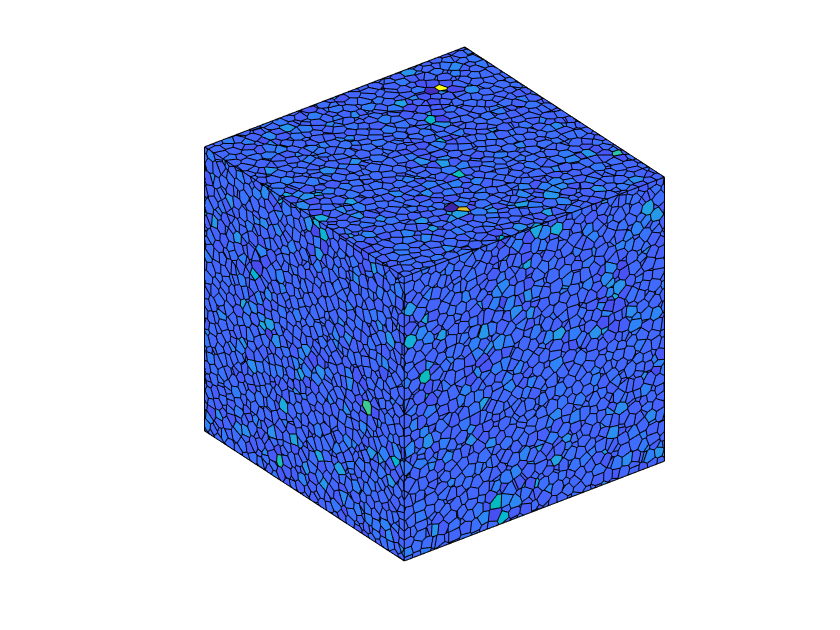


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plot the SP Laguerre tessellation for the largest number of grains

tic

% Compute the vertices, faces, neighbours (vfn) of the Laguerre diagram
[~,~,~,vfn]=mexPDall(bx,X,w,periodic); 

% Compute which cells lie on the boundary of the box (no need to plot the 
% interior cells since they are not visible)
[polys,cellids]=intersect_cells_on_boundary_periodic(bx,vfn);

% Colour the grains according to their volume
myc=generateGrainColours(actual_vols);

% Plot the Laguerre tessellation
figure
patchpolygons(polys,cellids,myc);
view([-37.5,30])
axis equal
axis off

drawnow

toc

Elapsed time is 77.760268 seconds.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Compute the dual phase run times (r=5)

% Initialise an array to store the run times
runtimes_DP=zeros(size(numGrains)); 

for k=1:length(numGrains)

    n=numGrains(k); % number of grains

    fprintf('Calculating run times for n = %d\n',n);

    % Initialise the seed locations randomly
    x0=L1*rand(n,1);
    y0=L2*rand(n,1);
    z0=L3*rand(n,1);
    X0=[x0,y0,z0];

    % Specify the desired volumes of the grains. These are stored in a 
    % column vector called target_vols.
    n1 = n/2; % n1 grains of ferrite (large grains)
    n2 = n/2; % n2 grains of martensite (small grains)
    % Set the volume ratio r: The ferrite grains are r times the volume of 
    % the martensite grains
    r = 5; 
    target_vols=[ones(n1,1);r*ones(n2,1)];
    % Normalise the volumes so that they add to the volume of the box
    target_vols=L1*L2*L3*target_vols/sum(target_vols);

    % Time Algorithm 2
    tic
    [X,w,percent_error,actual_vols]=...
    algorithm2(bx,X0,target_vols,periodic,tol,numLloyd,solver);
    t=toc;

    fprintf(' : completed in %f seconds\n',t);

    % Output the difference (percentage error) between the actual volumes 
    % of the grains and the target volumes
    disp(strcat('Maximum percentage error = ',num2str(percent_error),'%'));

    % Store the run time
    runtimes_DP(k)=t;

end

Calculating run times for n = 1000


Lloyd iteration:1
Lloyd iteration:2


Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 1.966283 seconds


Maximum percentage error =0.0042236%


Calculating run times for n = 2000


Lloyd iteration:1
Lloyd iteration:2


Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 3.323369 seconds


Maximum percentage error =0.0031325%


Calculating run times for n = 3000


Lloyd iteration:1
Lloyd iteration:2


Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 5.754886 seconds


Maximum percentage error =0.022567%


Calculating run times for n = 5000


Lloyd iteration:1
Lloyd iteration:2


Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 12.410892 seconds


Maximum percentage error =0.013875%


Calculating run times for n = 7500


Lloyd iteration:1
Lloyd iteration:2


Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 22.163817 seconds


Maximum percentage error =0.012015%


Calculating run times for n = 10000


Lloyd iteration:1
Lloyd iteration:2


Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 28.765309 seconds


Maximum percentage error =0.025399%


Calculating run times for n = 15000


Lloyd iteration:1
Lloyd iteration:2


Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 49.227603 seconds


Maximum percentage error =0.015423%


Calculating run times for n = 20000


Lloyd iteration:1
Lloyd iteration:2


Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5


 : completed in 84.244292 seconds


Maximum percentage error =0.015831%


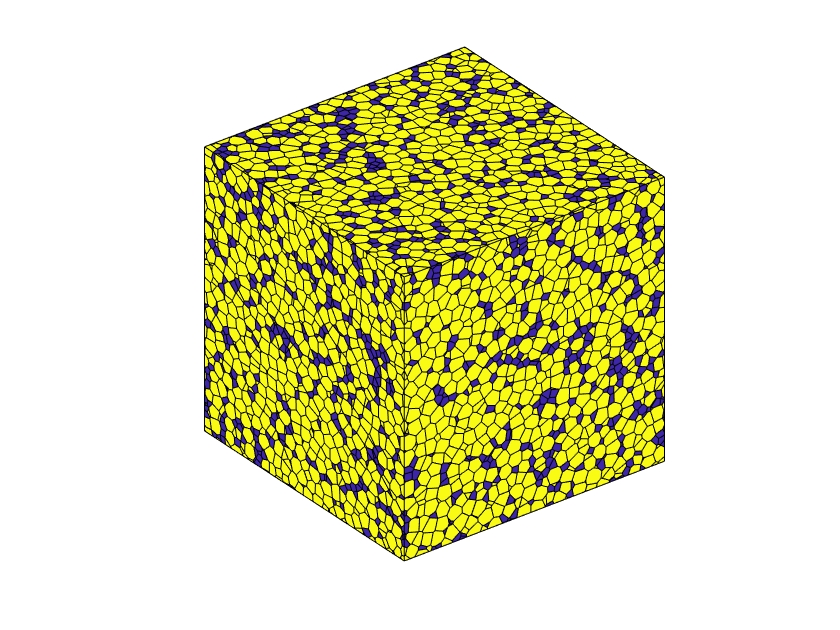

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plot the DP Laguerre tessellation for the largest number of grains

tic

% Compute the vertices, faces, neighbours (vfn) of the Laguerre diagram
[~,~,~,vfn]=mexPDall(bx,X,w,periodic); 

% Compute which cells lie on the boundary of the box (no need to plot the 
% interior cells since they are not visible)
[polys,cellids]=intersect_cells_on_boundary_periodic(bx,vfn);

% Colour the grains according to their volume
myc=generateGrainColours(actual_vols);

% Plot the Laguerre tessellation
figure
patchpolygons(polys,cellids,myc);
view([-37.5,30])
axis equal
axis off

drawnow

toc

Elapsed time is 78.438256 seconds.


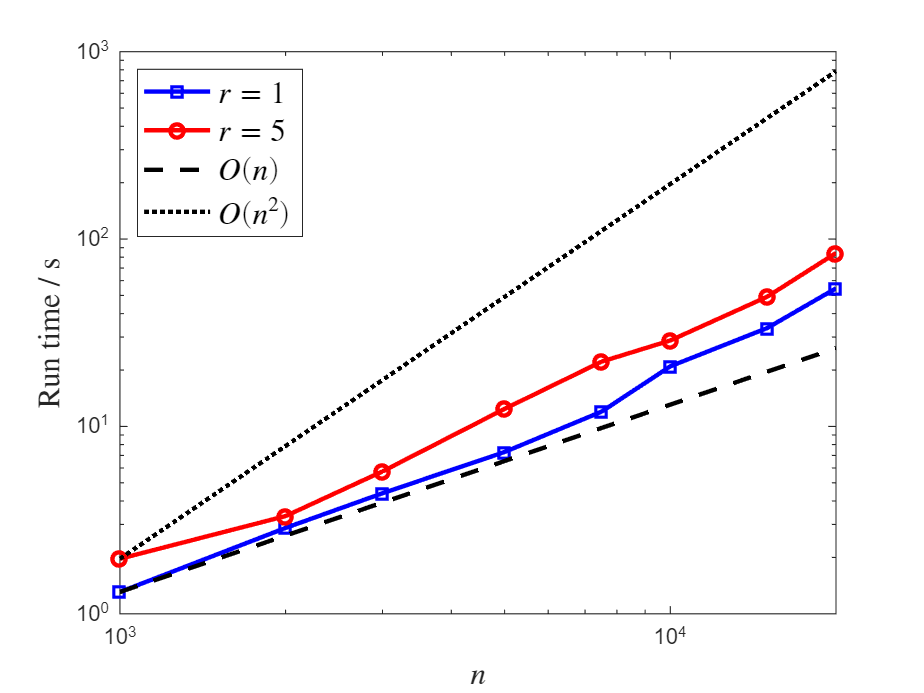


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plot the run times (create Figure 6 from the paper)

figure
loglog(numGrains,runtimes_SP,'b-s','LineWidth',2);
hold on
loglog(numGrains,runtimes_DP,'r-o','LineWidth',2);
c=exp(log(runtimes_SP(1))-log(numGrains(1)));
loglog(numGrains,c*numGrains,'k--','LineWidth',2);
c=exp(log(runtimes_DP(1))-2*log(numGrains(1)));
loglog(numGrains,c*numGrains.^2,'k:','LineWidth',2);
xlabel('$n$','FontSize',14,'interpreter','latex');
ylabel('Run time / s','Fontsize',14,'interpreter','latex');
legend('$r=1$','$r=5$','$O(n)$','$O(n^2)$','Fontsize',14,...
    'interpreter','latex','Location','northwest');